load('C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map_data4.mat')
map = Map;
load ("C:\Users\msi\OneDrive - Óbudai egyetem\0_Szakdolgozat\MATLAB_Scripts\2D\occupancy_map4.mat")
Map = occupancyMap(omap);

Data;
format bank

ss = stateSpaceSE2;
ss.StateBounds = [[0 50]; [0 50]; [-3.1416 3.1416]];
sv = validatorOccupancyMap(ss);

sv.Map = Map;
sv.ValidationDistance = 0.01;
ss.StateBounds = [Map.XWorldLimits;Map.YWorldLimits;[-pi pi]];

tic
planner = plannerHybridAStar(sv)

planner =   plannerHybridAStar with properties:

               StateValidator: [1×1 validatorOccupancyMap]
             MinTurningRadius: 2.00
        MotionPrimitiveLength: 2.00
          NumMotionPrimitives: 5.00
                  ForwardCost: 1.00
                  ReverseCost: 3.00
       DirectionSwitchingCost: 0
    AnalyticExpansionInterval: 5.00
        InterpolationDistance: 1.00


refpath = plan(planner,robot_pose,goal_pose,SearchMode='exhaustive');
refpath.States

ans =           5.00          8.00             0
          6.00          8.00             0
          7.00          8.00             0
          8.00          8.00             0
          9.00          8.00             0
          9.96          8.24          0.50
         10.71          8.96          1.00
         11.28          9.84          1.00
         11.85         10.72          1.00
         12.42         11.60          1.00


toc

Elapsed time is 0.149071 seconds.


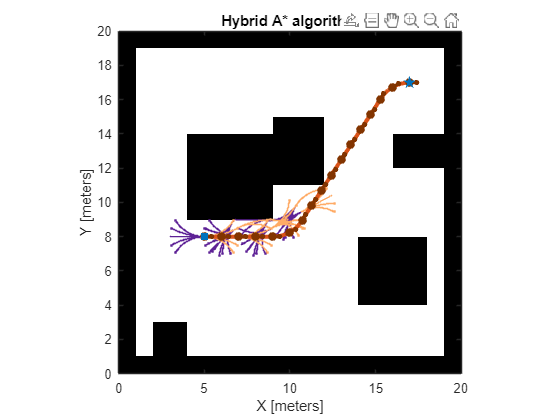

show(planner)
title("Hybrid A* algorithm")

Data = [refpath.States(:,1) refpath.States(:,2)]

Data =           5.00          8.00
          6.00          8.00
          7.00          8.00
          8.00          8.00
          9.00          8.00
          9.96          8.24
         10.71          8.96
         11.28          9.84
         11.85         10.72
         12.42         11.60


[m,systemview] = memory;
sprintf('%.0f MB',m.MemUsedMATLAB/(1024^2))

ans = '3965 MB'